clear all
%Paramètres de la tendance
kappa=0.194; %vitesse de retour à la moyenne
A=6.38; %temperature moyenne annuelle
B=0.0001; 
phi=-154.76;
C=10.44;
omega=365;

%paramètre de la volatilité
gamma=sqrt(6.12);



## Question 1 


fun = @dtheta

fun = function_handle with value:
    @dtheta


x1 = fzero(fun,1)

x1 = 27.7077

x2 = fzero(fun,210)

x2 = 210.2723

Tq1 = theta(x1)

Tq1 = -4.0572

Tq2 = theta(x2)

Tq2 = 16.8410

## Question 2 


Tinitiale=-1;
tmax=366;
T1=zeros(1,tmax);
T1(1)=Tinitiale;
for i=2:tmax
    T1(i)= T1(i-1) + kappa *(theta(i-1)-T1(i-1)) + dtheta(i-1) + gamma*normrnd(0,1);
end

t = linspace(1,366,366);
plot(t,T1)
hold on
T = theta(t);
plot(t,T)
hold off


## Question 3 

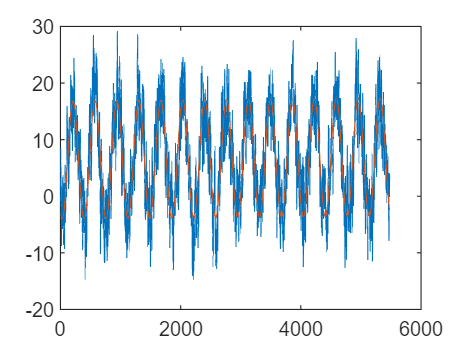


Tinitiale=-1;
tmax= 365*15+1;
T15=zeros(1,tmax);
T15(1)=Tinitiale;
for i=2:tmax
    T15(i)= T15(i-1) + kappa *(theta(i-1)-T15(i-1)) +dtheta(i-1) + gamma*normrnd(0,1);
end

t2 = linspace(1,365*15+1,365*15+1);
plot(t2,T15)
hold on
plot(t2,theta(t2))
hold off

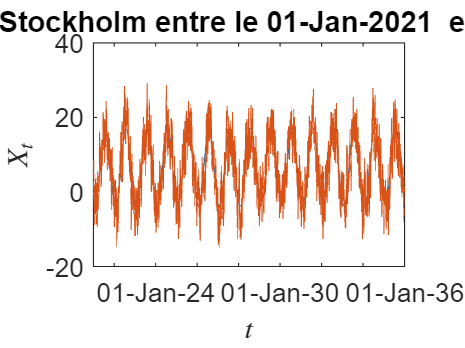



date = datetime('01-Jan-2021') + caldays(0:tmax+2); % créer un vecteur avec toutes les dates du 1 janvier 2021 au 1 janvier 2026.
% La boucle suivant enlève les 29 février des années bissectiles
for j = [2024:4:2035]
    indice = date ~= strcat("29-Feb-",int2str(j));
    date = date(indice);
end

plot(date,theta(t2))
hold on
plot(date,T15)
xtickformat('dd-MMM-yy')
xlabel('$t$','interpreter','latex','FontSize',12)
ylabel('$X_t$','interpreter','latex','FontSize',12)
set(gca,'fontsize',12)
title(sprintf('Temperature Stockholm entre le %s  et le %s',date(1),date(tmax)))

## Question 4 


N_MC=1000;
n=1948; %3 mai 2026
tmax=n;
Tinitiale=-1;
S_valeur = 0;
S_ecart = 0;
for j = 1 : N_MC
    T = zeros(1,tmax);
    T(1)= Tinitiale;
    for i = 2:tmax
        T(i)= T(i-1) + kappa *(theta(i-1)-T(i-1)) +dtheta(i-1) + gamma*normrnd(0,1);
    end
    S_valeur = S_valeur + T(n);
    S_ecart = S_ecart + T(n)^2;
end
Tmoy = S_valeur/N_MC

Tmoy = 7.3447

Ecart_type = sqrt(S_ecart/N_MC - Tmoy^2)

Ecart_type = 4.1462

q = norminv(0.975)
intervalle_conf = [Tmoy - q*Ecart_type/sqrt(N_MC), Tmoy + q*Ecart_type/sqrt(N_MC)]

intervalle_conf =     7.0877    7.6017


## Question 5

%p = S/N_MC
Tinitiale=-1;
N_MC=1000;
d = 1 ;
n = 12*365+31+28+31+30+31+30+31 + d;
tmax=n;
S= 0;
Moy = 0;
Ecart = 0;
for j = 1 : N_MC
    T = zeros(1,tmax);
    T(1) = Tinitiale;
    for i = 2:tmax
        T(i)= T(i-1) + kappa *(theta(i-1)-T(i-1)) +dtheta(i-1) + gamma*normrnd(0,1);
    end
    if T(n)>= 25
        S = S + 1;
    end
    Moy = Moy + T(n);
    Ecart = Ecart + T(n)^2;
end 
p = S/N_MC

p = 0.0410

Moy = Moy/N_MC

Moy = 17.3235

Ecart = sqrt(Ecart/N_MC - Moy^2)

Ecart = 4.3249




%Il faut 1.96*Ecart_type/sqrt(N_MC)<0.1
% soit 1.96*
N = ((1.96*Ecart)/0.1)^2

N = 7.1855e+03